# Initialization Script

In this script, we will be determining the appropriate settings for our filters to remove the most noise from our images, enhancing the signal, and skeletonizing any line-like objects. We will then take these settings and apply them to the high-throughput script where we can run over an entire sequence of images with those settings. This script will be displaying figures that will allow us to guage how effective our preprocessing is.

### Guassian Blur Subtraction

To begin, we want to load a random ZMAX tile from our image sequence and optimize our preprocessing settings. Ensure there is enough innervation in the tile so we can actually see if noise is being removed.

Load the tile.

pic = imread('0747_zmax.tif');

Take a heavy gaussian blur of the tile.

heavygaussian = imgaussfilt(pic, 150);

Subtract the heavy gaussian blur from the original tile.

subtracted = pic - heavygaussian;

Finally, we will take that subtracted image and we will do a small gaussian blur to broaden out the signal slightly before making a mask. 

lightgaussian = imgaussfilt(subtracted, 2);

Display for verification.

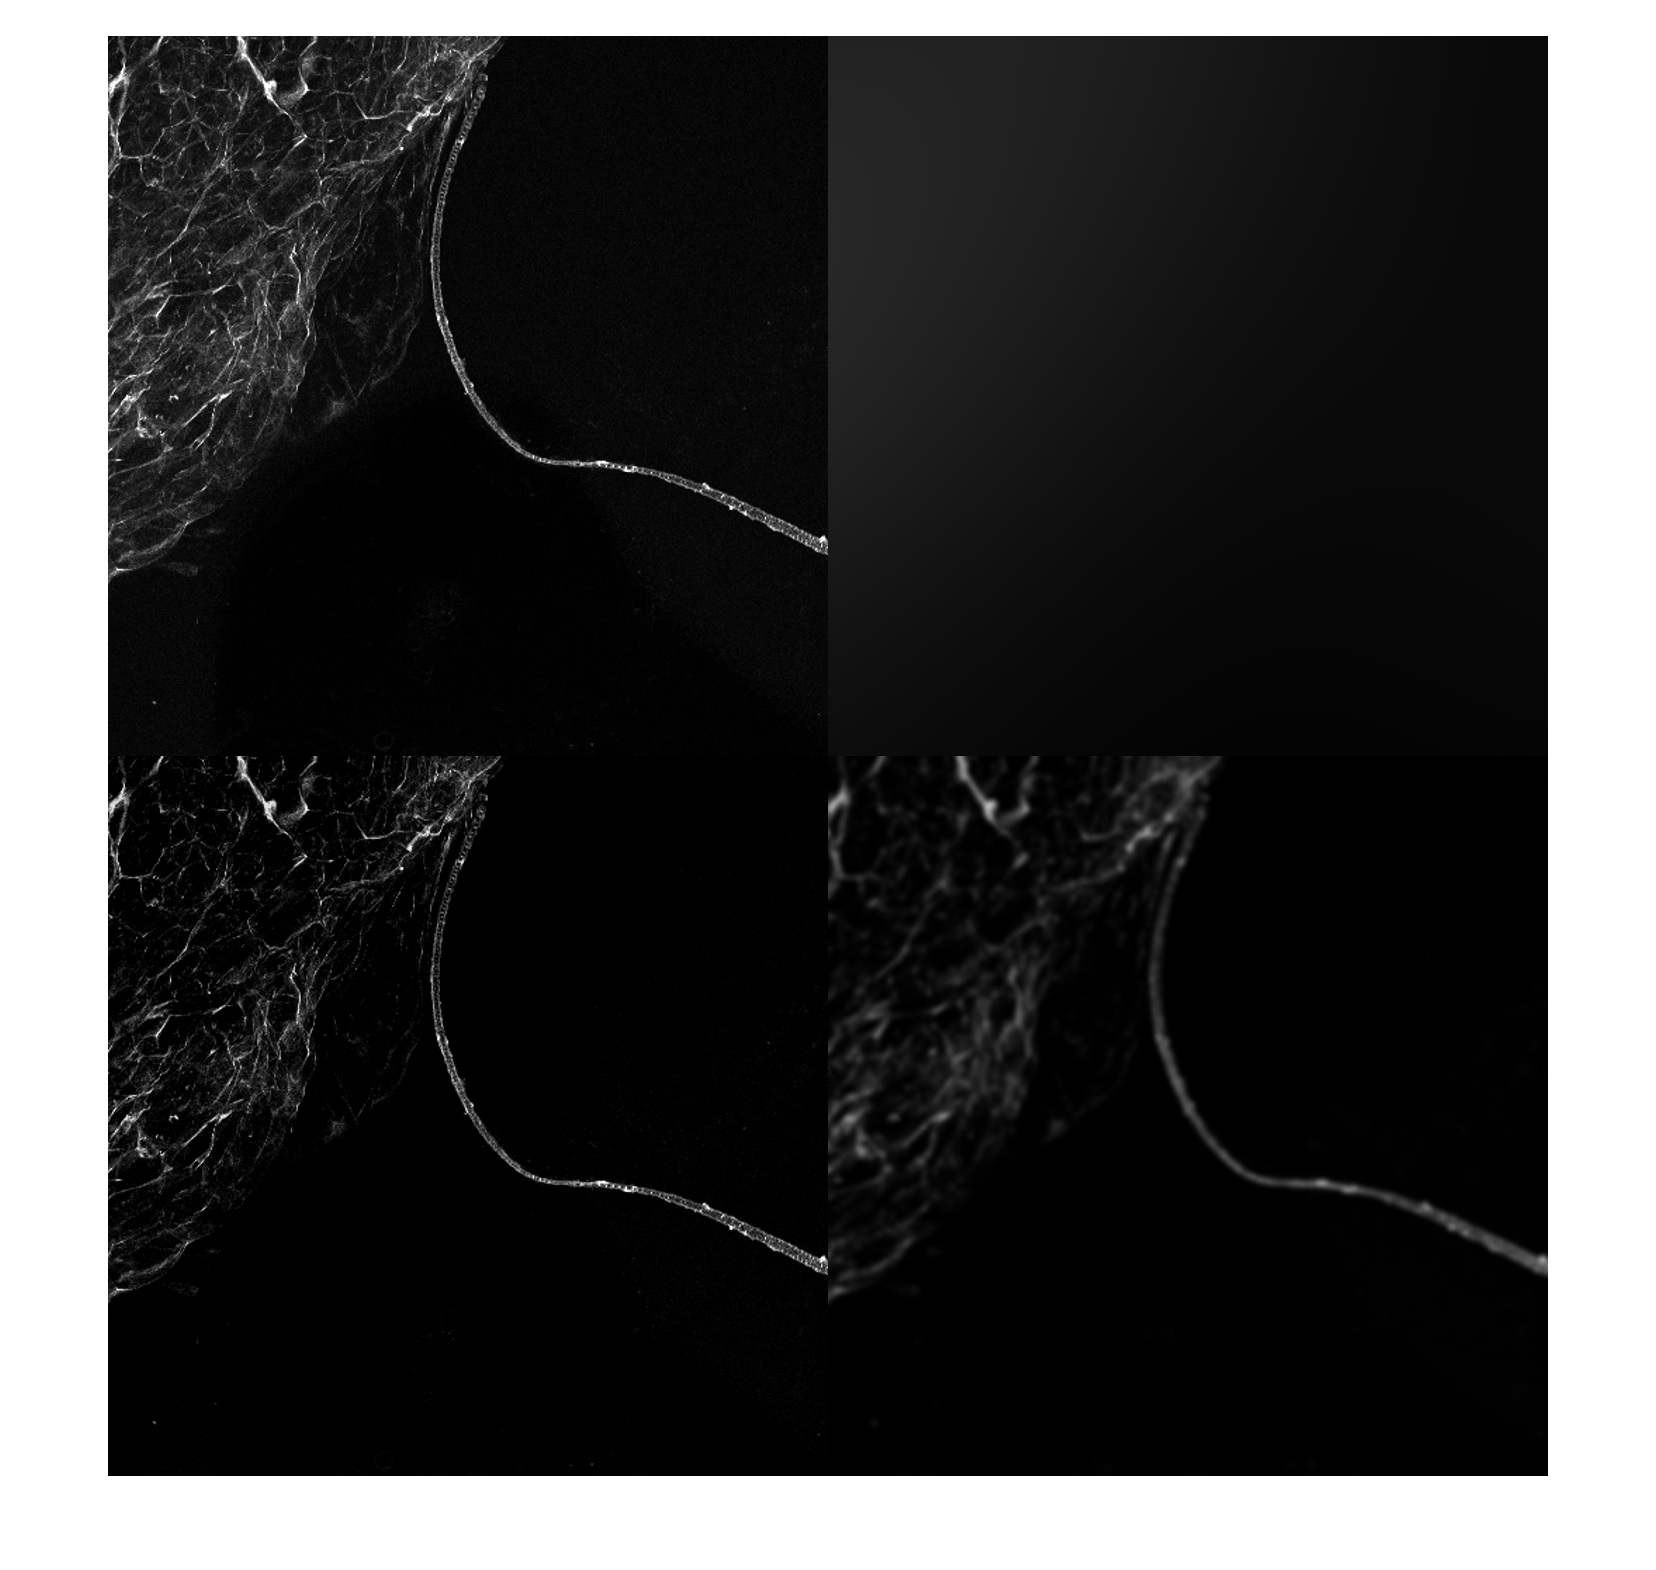

montage({pic, heavygaussian, subtracted, lightgaussian})

### Mask Binarization and Skeletonization

Now that we have processed the gaussian blur subtraction, we can begin to skeletonize the light gaussian blur we made.

First, we will create a mask and set a threshold of only keeping things whose pixel value (i.e. intenstiy) is greater that 4.

mask = lightgaussian > 4;

Next, we use the bwareaopen function to remove any objects in the image that are less than 40 pixels.

mask = bwareaopen(mask, 40);

Then, using the bwmorph function, we can take the mask and convert the mask into a binary image, using the "open" method.

mask = bwmorph(mask, 'open'); 

Finally, we take that binary mask and we use the bwskel function to skeletonize it, with the added feature of removing any branches that are less than 4 pixels long.

mskel = bwskel(mask, 'MinBranchLength', 4);

Here we can show the final product. Once you have run this process through one tile and determine the best values for the gaussian blurs, pick another image and run those settings over it and see if it still is effective. No settings will be perfect for every image in your sequence, but finding the sweet spot that effectively skeletonizes for your image is possible.

Once you feel like you have the appropriate settings, move to the high-throughput script where we can run over all your images in sequence.

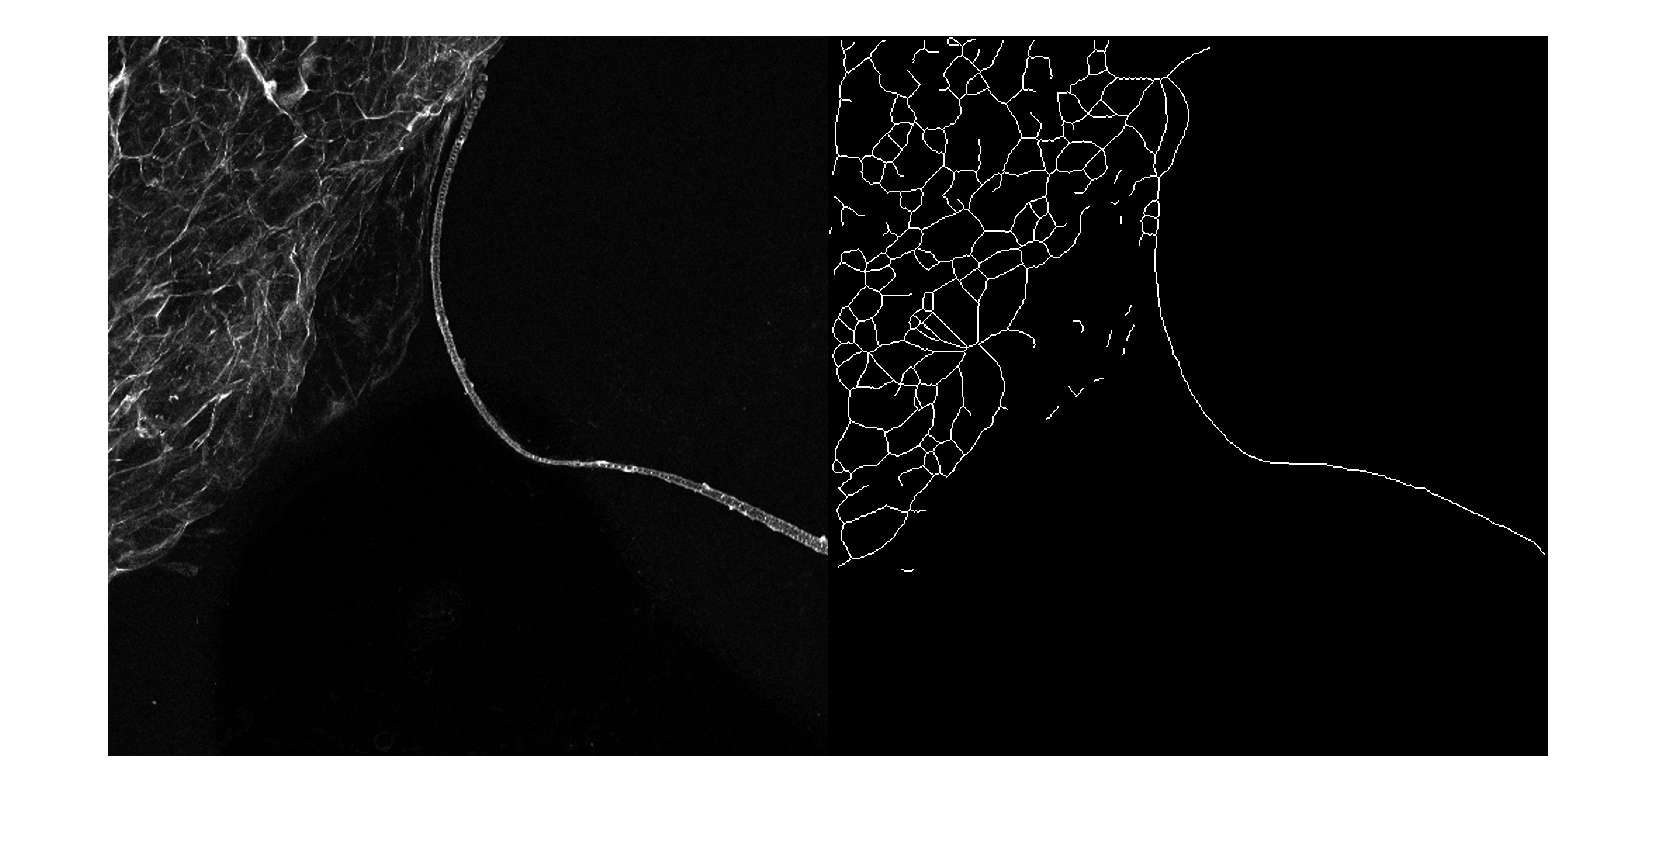

montage({pic, mskel});